close all; clear all;
% -- PLANE REPRESENTATION --------------------------------------
[x,y,z,var]=f_planeRep("Data_CrossSections/Coarse/CrossSections.txt");
[xR,yR,zR,varR]=f_planeRep("Data_CrossSections/Coarse/CrossSectionsR.txt");

% -- FLOW PROPERTIES -------------------------------------------
% 1 -> Static Pressure
% 2 -> Pressure Coefficient
% 3 -> Dynamic Pressure
% 4 -> Stagnation Pressure
% 5 -> Velocity magnitude
% 6 -> X-velocity
% 7 -> Y-velocity
% 8 -> Z-velocity
% 9 -> Velocity angle
% 10 -> Vorticity magnitude
% 11 -> X-vorticity
% 12 -> Y-vorticity
% 13 -> Z-vorticity
% 14 -> Turbulent kinetic energy
% 15 -> Turbulent intensity
% 16 -> Production of TKE
% 17 -> Turbulent Reynolds number
% 18 -> Cross-stream velocity magnitude
% 19 -> Cross-stream vorticity magnitude
v=14;
Sec=11;

% Bulk velocity
u_b=0;
u_bR=0;
c=1;
max=0;
maxR=0;
for i=1:size(var,1)
    for j=1:size(var,2)
        u_b=u_b+var(i,j,6,Sec);
        u_bR=u_bR+varR(i,j,6,Sec);
        c=c+1;
        if(var(i,j,18,Sec)>max)
            max=var(i,j,18,Sec);
        end
        if(varR(i,j,18,Sec)>maxR)
            maxR=varR(i,j,18,Sec);
        end
    end
end
u_b=u_b/(c-1);
u_bR=u_bR/(c-1);
max*100/u_b

ans = 1.4511

maxR*100/u_bR

ans = 0.4650

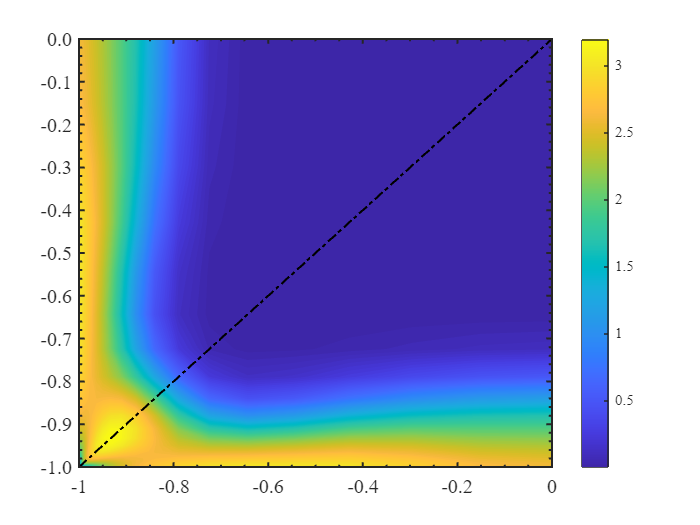

figure;
[Yv,Zv]=meshgrid(y/y(end),z/z(end));
contourf(Yv,Zv,var(:,:,v,Sec),100,'LineStyle','None');
colorbar;
hold on;
plot(-1:1/100:0,-1:1/100:0,"LineStyle","-.","Color","k","LineWidth",1.25);
hold off;
xlim([y(1)/y(end) 0]);
ylim([z(1)/z(end) 0]);

% Styling
set(gca,'yticklabel',num2str(get(gca,'ytick')','%.1f'))
fontname(gca,"Times New Roman")
set(gcf,'color','w');
set(gca,'XMinorTick','on','YMinorTick','on');
ax = gca;
ax.LineWidth = 1.2;
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;

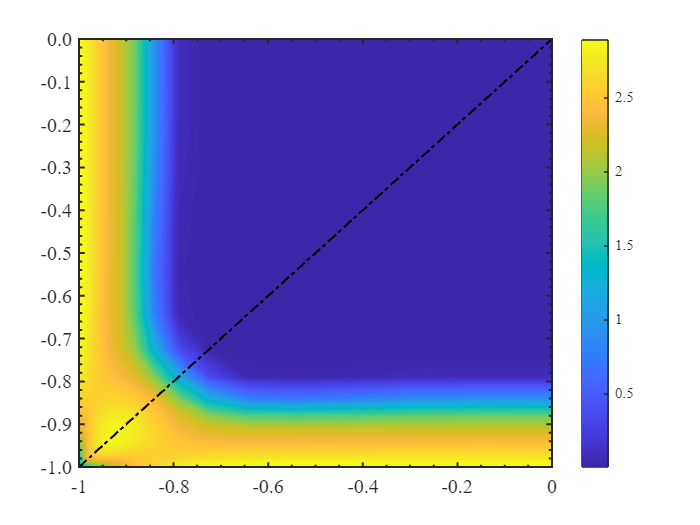


[YvR,ZvR]=meshgrid(yR/yR(end),zR/zR(end));
contourf(YvR,ZvR,varR(:,:,v,Sec),100,'LineStyle','None');
colorbar;
hold on;
plot(-1:1/100:0,-1:1/100:0,"LineStyle","-.","Color","k","LineWidth",1.25);
hold off;
xlim([yR(1)/yR(end) 0]);
ylim([zR(1)/zR(end) 0]);

% Styling
set(gca,'yticklabel',num2str(get(gca,'ytick')','%.1f'))
fontname(gca,"Times New Roman")
set(gcf,'color','w');
set(gca,'XMinorTick','on','YMinorTick','on');
ax = gca;
ax.LineWidth = 1.2;
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;

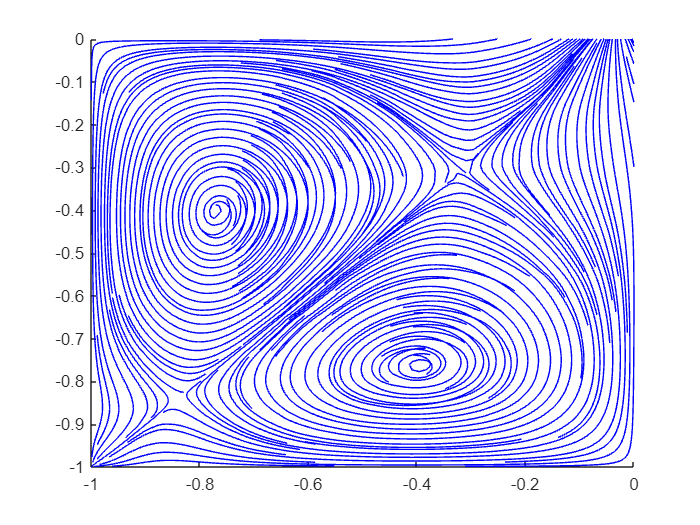

figure;
streamslice(Yv,Zv,transpose(var(:,:,7,Sec)),transpose(var(:,:,8,Sec)),20,'noarrows');
xlim([-1 0]);
ylim([-1 0]);

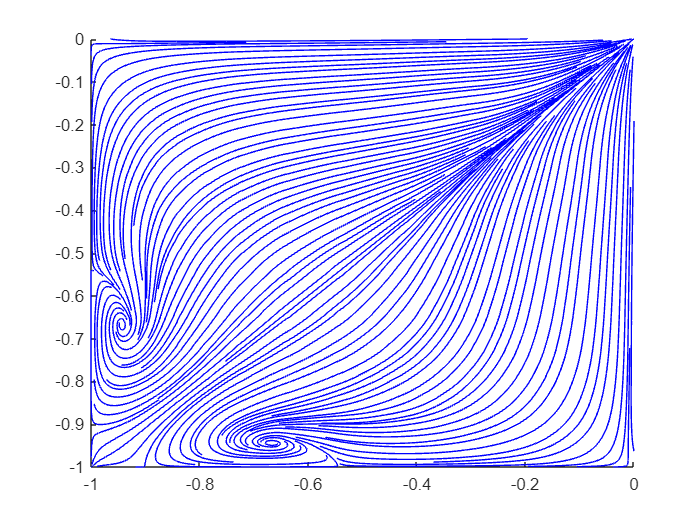


figure;
streamslice(YvR,ZvR,transpose(varR(:,:,7,Sec)),transpose(varR(:,:,8,Sec)),20,'noarrows');
xlim([-1 0]);
ylim([-1 0]);

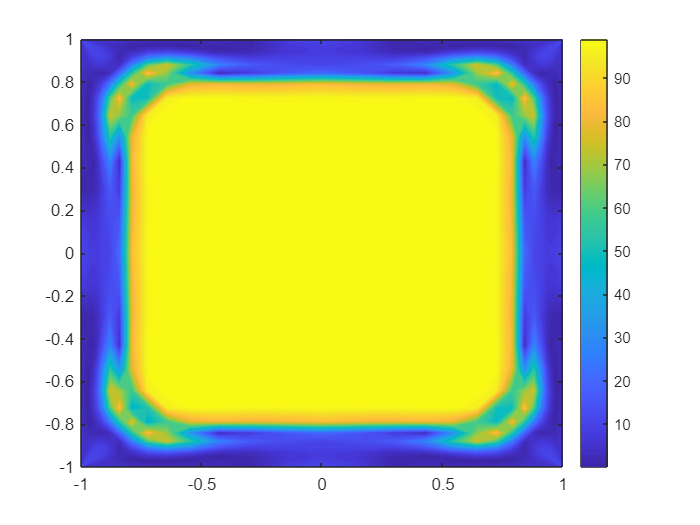

% COMPARISON WITH K-W-SST
v=14;
Sec=11;
error=[];
for i=1:size(var,1)
    for j=1:size(var,2)
        error(i,j)=abs(var(i,j,v,Sec)-varR(i,j,v,Sec))*100/abs(var(i,j,v,Sec));
    end
end

figure;
contourf(Yv,Zv,error,100,'LineStyle','None');
colorbar;


% Bulk velocity
max=0;
for i=1:size(var,1)
    for j=1:size(var,2)
        if(error(i,j)>max)
            max=error(i,j);
        end

    end
end
max

max = 100.0000